# **Basic Operations, Functions, and Commands in MATLAB**

# Useful Links

[What Is a Live Script or Function?](https://se.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html)

[Create Live Scripts in the Live Editor](https://se.mathworks.com/help/matlab/matlab_prog/create-live-scripts.html)

[Matlab Cheat Sheet](https://github.com/krishnr/MATLAB-cheat-sheet)

[Matlab Cheat Sheet 2](https://github.com/jousefm/Matlab-Cheat-Sheet/blob/master/MatlabCheatsheet.pdf)

# Quick Review of Matlab Commands

#### Vector and Matrix Arithmetic

- `+` Addition: `[1 1 1] + [1 2 3] = [2 3 4]`

- `-` Subtraction: `[1 1 1] - [1 2 3] = [0 -1 -2]`

- `.*` Element-wise multiplication: `3 .* [1 2 3] = [3 6 9]`

- `./` Element-wise division: `[3 6 9] ./ 3 = [1 2 3]`

- `*` Matrix multiplication: `[1 3; 2 4] * [3 0; 1 5] = [6 15; 10 20]`

- `'` Transpose: `[1 2 3]' = [1; 2; 3]`

- `inv()` Inverse of a matrix: `inv([1 2; 3 4]) = [-2 1; 1.5 -0.5]`

- `det()` Determinant of a matrix: `det([1 2; 3 4]) = -2`

- `rank()` Rank of a matrix: `rank([1 2; 3 4]) = 2`

- `eig()` Eigenvalues and eigenvectors of a matrix: `[V, D] = eig([1 2; 3 4])`

#### Plotting

- `plot(x,y)` Plotting a 2D line graph: `x = [0:0.1:2*pi]; y = sin(x); plot(x,y)`

- `scatter(x,y)` Plotting a 2D scatter plot: `x = randn(100,1); y = randn(100,1); scatter(x,y)`

- `histogram(x)` Plotting a histogram: `x = randn(1000,1); histogram(x)`

- `bar(x)` Plotting a bar chart: `x = [1 2 3]; bar(x)`

- `surf(x,y,z)` Plotting a 3D surface plot: `[X,Y] = meshgrid(-2:.2:2); Z = X .* exp(-X.^2 - Y.^2); surf(X,Y,Z)`

- `contour(x,y,z)` Plotting a 2D contour plot: `[X,Y] = meshgrid(-2:.2:2); Z = X .* exp(-X.^2 - Y.^2); contour(X,Y,Z)`

- `quiver(x,y,u,v)` Plotting a 2D vector field: `[x,y] = meshgrid(-2:.2:2); u = cos(x).*y; v = sin(x).*y; quiver(x,y,u,v)`

#### Other Useful Commands

- `size()` Size of a matrix: `A = [1 2 3; 4 5 6]; size(A) = [2 3]`

- `length()` Length of a vector: `x = [1 2 3]; length(x) = 3`

- `zeros()` Creating a matrix of zeros: `zeros(2,3) = [0 0 0; 0 0 0]`

- `ones()` Creating a matrix of ones: `ones(2,3) = [1 1 1; 1 1 1]`

- `eye()` Creating an identity matrix: `eye(3) = [1 0 0; 0 1 0; 0 0 1]`

- `diag()` Extracting the diagonal of a matrix: `A = [1 2 3; 4 5 6; 7 8 9]; diag(A) = [1 5 9]`

- `max()` Maximum value of a matrix or vector: `A = [1 2 3; 4 5 6]; max(A) = 6`

- `min()` Minimum value of a matrix or vector: `A = [1 2 3; 4 5 6]; min(A) = 1`

- `Function: write your functions at the end of the script to be able to use them during the script while running`

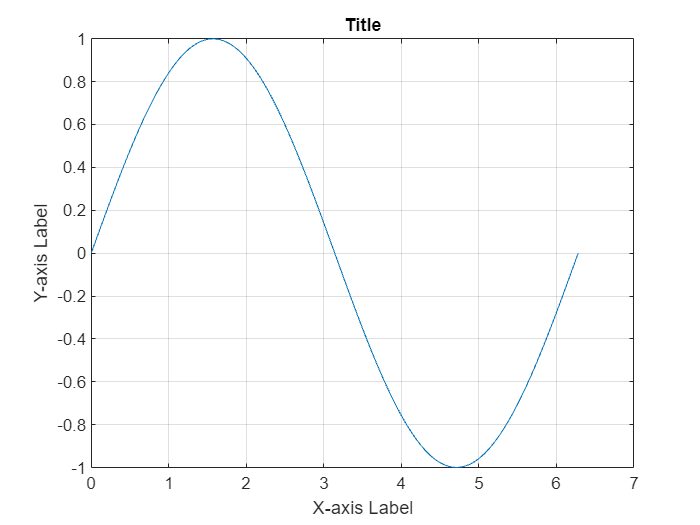

% function output = function_name(input1,input2)
%     output = input1+input2
%     disp(['output = ', num2str(output)])
% end

#### Transfer Functions

- Convert state-space representation to transfer function: `ss2tf(A,B,C,D)`

- Create a continuous-time transfer function model: `sys = tf(numerator, denominator)`

- `Plot the bode diagram of the system:`` bode(sys)`

- Create a discrete-time transfer function model: `sys = tf(numerator, denominator, ts)`

#### Steady States

- Plot the step response of a dynamic system model: `step(sys)`

- Compute the state-space model of a transfer function: `ss(A,B,C,D): `A = [-1.2,-1.6,0;1,0,0;0,1,0]; B = [1;0;0]; C = [0,0,1]; D = 0; sys = ss(A,B,C,D);

#### Solving Ordinary Differential Equations (ODEs)

- `ode45`: Solves ODEs using a variable step Runge-Kutta method. Example: `ode45(@func, [t0, tf], y0)`, where `func` is the function that defines the ODE, `[t0, tf]` is the time interval, and `y0` is the initial condition.

- `ode23`: Solves ODEs using a variable step method based on an Adams-Bashforth-Moulton PECE algorithm. Example: `ode23(@func, [t0, tf], y0)`.

- `ode113`: Solves ODEs using a variable order method based on an Adams-Bashforth-Moulton PECE algorithm. Example: `ode113(@func, [t0, tf], y0)`.

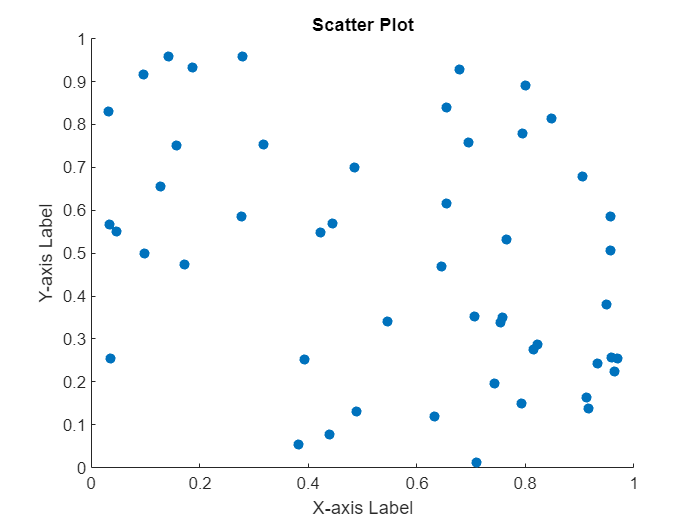

% Basic Plotting
clear all; close all
% Create a simple line plot
x = linspace(0, 2*pi, 100);
y = sin(x);
plot(x, y);

xlabel('X-axis Label');
ylabel('Y-axis Label');
title('Title');
grid on;

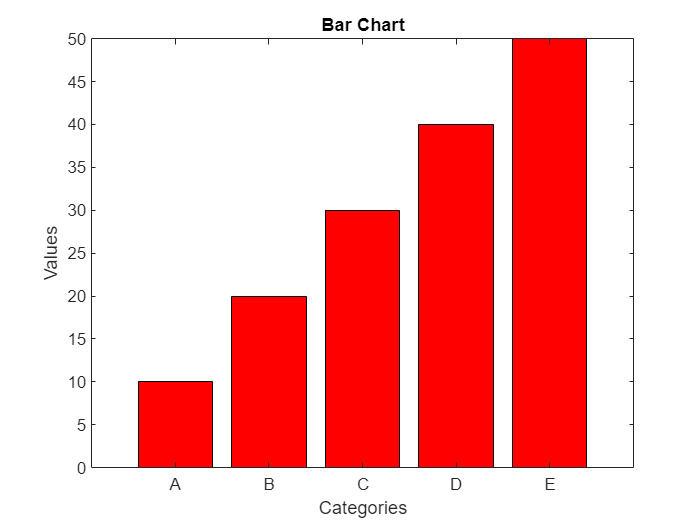

clear all; close all
% Create a scatter plot
x = rand(1, 50);
y = rand(1, 50);
scatter(x, y, 'filled');

xlabel('X-axis Label');
ylabel('Y-axis Label');
title('Scatter Plot');

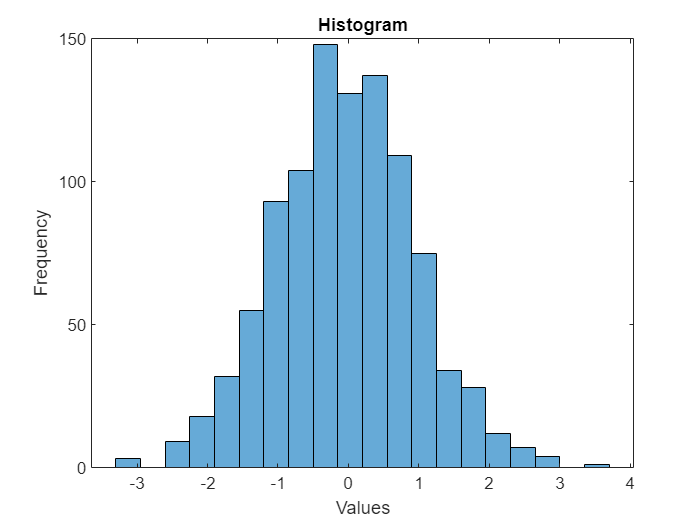

clear all; close all
% Create a Bar chart
categories = categorical({'A', 'B', 'C', 'D', 'E'});
data = [10 20 30 40 50];
bar(categories, data, 'FaceColor', 'red')

xlabel('Categories');
ylabel('Values');
title('Bar Chart');

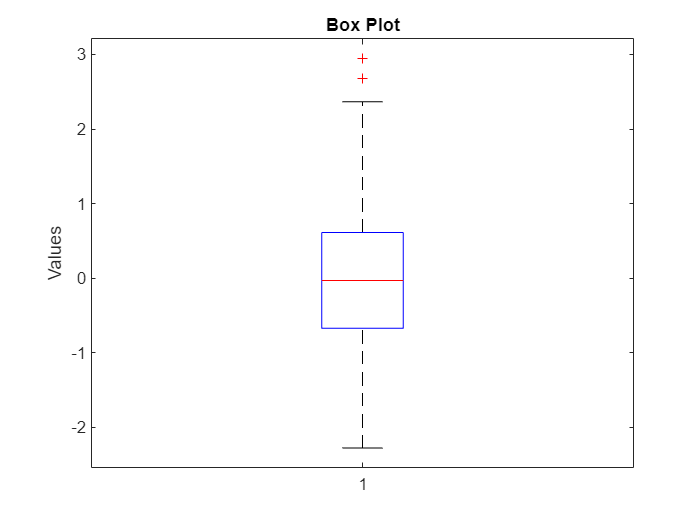

clear all; close all
% Create a histogram
data = randn(1, 1000);
histogram(data, 20); % Adjust the number of bins as needed
xlabel('Values');

ylabel('Frequency');
title('Histogram');


clear all; close all
% Create a box plot
data = randn(1, 100);
boxplot(data);
ylabel('Values');
title('Box Plot');


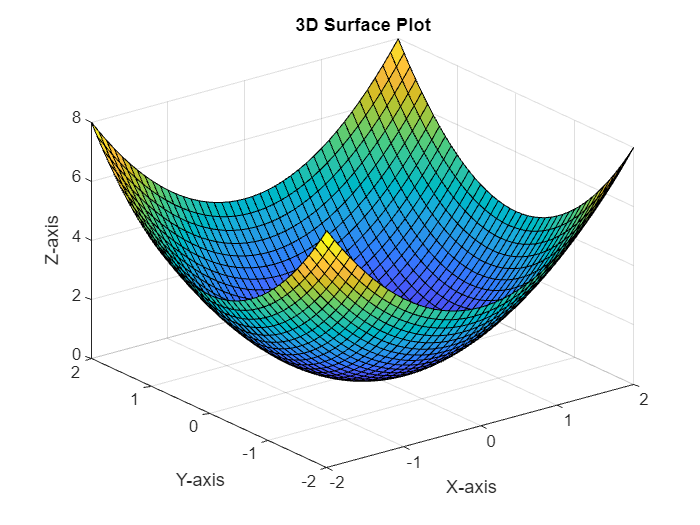

clear all; close all

% Create a 3D surface plot
[X, Y] = meshgrid(-2:0.1:2);
Z = X.^2 + Y.^2;
surf(X, Y, Z);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('3D Surface Plot');


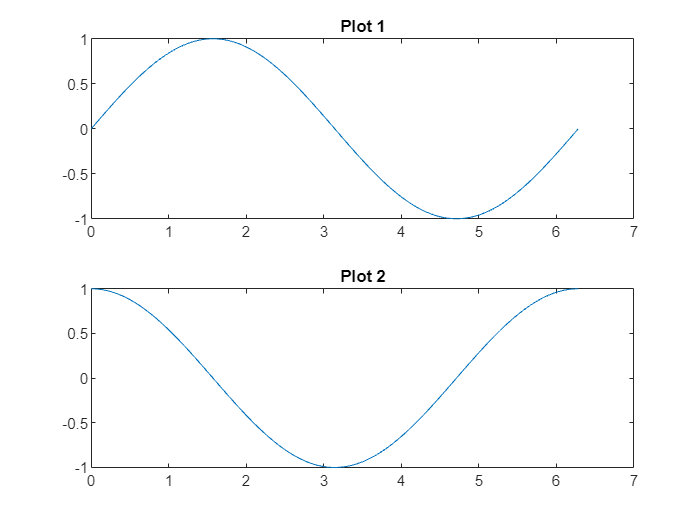

clear all; close all
% Create multiple plots in one figure
x = linspace(0, 2*pi, 100);
y1 = sin(x);
y2 = cos(x);

subplot(2, 1, 1); % 2 rows, 1 column, first plot
plot(x, y1);
title('Plot 1');

subplot(2, 1, 2); % 2 rows, 1 column, second plot
plot(x, y2);
title('Plot 2');


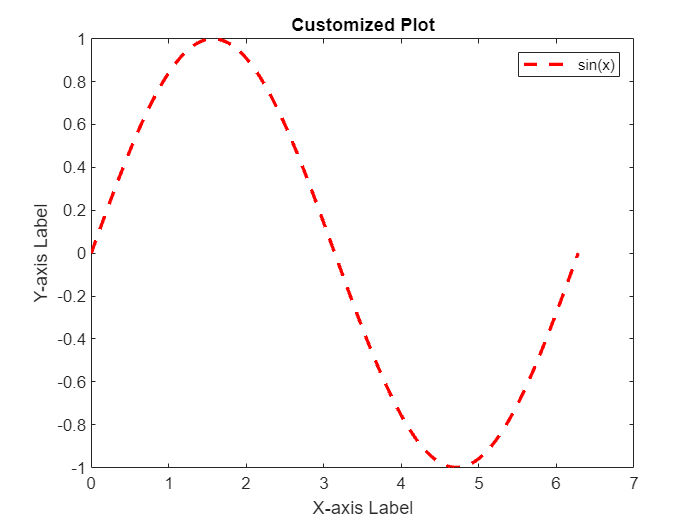

clear all; close all
% Customizing plots
x = linspace(0, 2*pi, 100);

y = sin(x);
plot(x, y, 'r--', 'LineWidth', 2);
xlabel('X-axis Label');
ylabel('Y-axis Label');
title('Customized Plot');
legend('sin(x)');

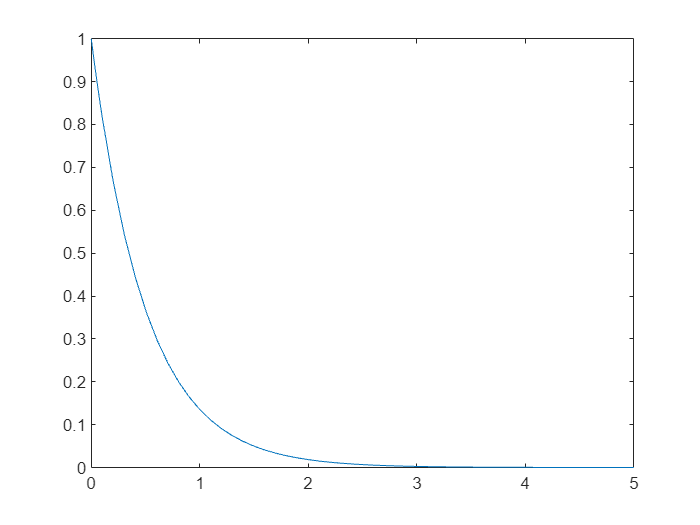

clear all; close all
% Define the ODE: dy/dx = -2y

f = @(x, y) -2*y;
xspan = [0, 5];  % Time span
y0 = 1;          % Initial condition
[x, y] = ode45(f, xspan, y0);
plot(x, y);